%% Second-order staggered solver: spatial convergence experiment
% This experiment uses the exact standing-wave solution
%
%   p(x,t) = sin(pi*x) cos(pi*t),
%   v(x,t) = -cos(pi*x) sin(pi*t),
%
% for K = B = 1 on 0 <= x <= 1 with homogeneous pressure boundary
% conditions. The time step is chosen as dt = O(dx^2), making the
% second-order temporal error O(dx^4), so it does not mask the expected
% second-order spatial error.

clear; close all; clc;

%% Experiment parameters
pointCounts = [21,41,81,161];
finalTime = 0.05;
timeStepFactor = 0.15;
expectedOrder = 2;

medium = AcousticMedium1D.constant(KappaValue=1,BetaValue=1);
pExact = @(x,t) sin(pi*x).*cos(pi*t);

numberOfRuns = numel(pointCounts);
h = zeros(numberOfRuns,1);
dt = zeros(numberOfRuns,1);
numberOfSteps = zeros(numberOfRuns,1);
errorInf = zeros(numberOfRuns,1);
errorL2 = zeros(numberOfRuns,1);

%% Run the refinements
for j = 1:numberOfRuns
    gridx = GridSpace1D(Grid1DUnifPrimal([0,1],pointCounts(j)));
    h(j) = gridx.h;

    targetDt = timeStepFactor*h(j)^2;
    numberOfSteps(j) = ceil(finalTime/targetDt);
    computationalTimes = linspace(0,finalTime,numberOfSteps(j)+1);
    dt(j) = computationalTimes(2)-computationalTimes(1);

    solver = AcousticSolver1DStaggered( ...
        gridx,computationalTimes,gridx,finalTime,medium,SpatialOrder=2);
    [pressure,~] = solver.solve(@(x) pExact(x,0),@(x) 0*x);

    exactFinal = pExact(gridx.x.pts,finalTime);
    pressureError = pressure.values(:,end)-exactFinal;
    errorInf(j) = norm(pressureError,inf);
    errorL2(j) = sqrt(h(j))*norm(pressureError,2);
end

%% Compute observed orders
orderInf = nan(numberOfRuns,1);
orderL2 = nan(numberOfRuns,1);
for j = 2:numberOfRuns
    refinementRatio = h(j-1)/h(j);
    orderInf(j) = log(errorInf(j-1)/errorInf(j))/log(refinementRatio);
    orderL2(j) = log(errorL2(j-1)/errorL2(j))/log(refinementRatio);
end

results = table(pointCounts(:),h,dt,numberOfSteps,errorInf,errorL2, ...
    orderInf,orderL2,VariableNames=["N","dx","dt","TimeSteps", ...
    "MaxError","DiscreteL2Error","MaxOrder","DiscreteL2Order"])

results = 4×8 table
     N       dx           dt        TimeSteps     MaxError     DiscreteL2Error    MaxOrder    DiscreteL2Order
    ___    _______    __________    _________    __________    _______________    ________    _______________

     21       0.05    0.00037313       134       2.5241e-05      1.7848e-05           NaN            NaN     
     41      0.025    9.3633e-05       534       6.3143e-06      4.4649e-06        1.9991         1.9991     
     81     0.0125     2.343e-05      2134       1.5788e-06      1.1164e-06        1.9998         1.9998     
    161    0.00625    5.8589e-06      8534       3.9473e-07      2.7911e-07        1.9999         1.9999     

	

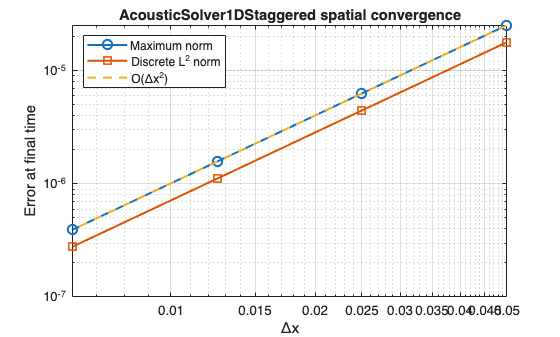


%% Plot convergence
figure;
loglog(h,errorInf,'-o',LineWidth=1.5,MarkerSize=7); hold on;
loglog(h,errorL2,'-s',LineWidth=1.5,MarkerSize=7);
referenceError = errorInf(1)*(h/h(1)).^expectedOrder;
loglog(h,referenceError,'--',LineWidth=1.5);
grid on;
xlabel('\Deltax');
ylabel('Error at final time');
title('AcousticSolver1DStaggered spatial convergence');
legend('Maximum norm','Discrete L^2 norm','O(\Deltax^2)', ...
    Location='northwest');


%% Summary
fprintf('Expected spatial order: %d\n',expectedOrder);

Expected spatial order: 2


fprintf('Finest-grid maximum-norm order: %.4f\n',orderInf(end));

Finest-grid maximum-norm order: 1.9999


fprintf('Finest-grid discrete-L2 order: %.4f\n',orderL2(end));

Finest-grid discrete-L2 order: 1.9999
